% ------ CREATE A TRANSFORMATION MATRIX ------ %

eul = [0 pi/2 0]; % TEMP - matrix holds Z Y X rotations 
rotmZYX = eul2rotm(eul); % TEMP - matrix generates 3x3 rot matrix in Z-Y-X order (changeable!)
a = rotmZYX; % redundant - copy of rot matrix above
c = [1;2;3]; % load the translation column vector

b = zeros(4,4); % initialize empty hom. 4x4 matrix
b(1:3,1:3) = a; % insertion of rot 3x3 into hom. 4x4
b(1:3, 4) = c; % insertion of translation vector into 4x4
b(4,4) = 1; % insertion of view factor into 4x4
b % completed homogeneous 4x4 matrix

b =     0.0000         0    1.0000    1.0000
         0    1.0000         0    2.0000
   -1.0000         0    0.0000    3.0000
         0         0         0    1.0000


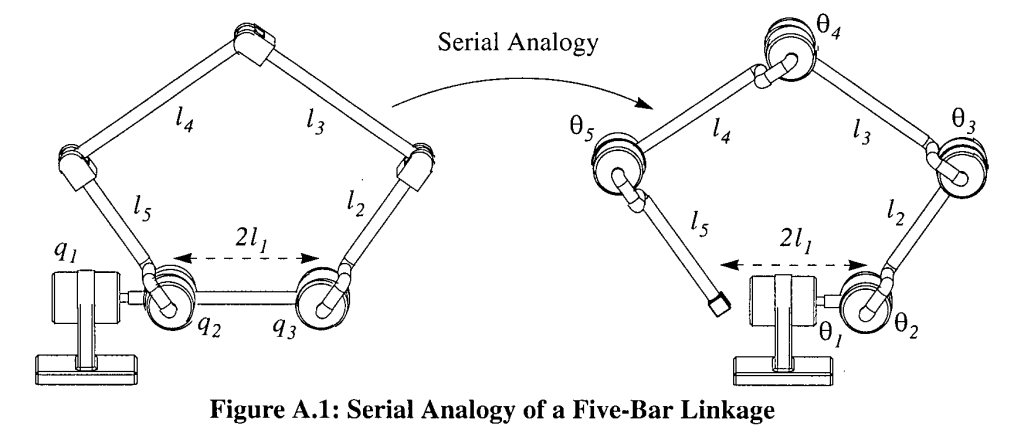

% ------ Five-bar with shoulder (ref. Stocco's thesis) ---------------

% NOTE: for utility of this model we only need to translate base frame to
% the end effector @ theta4, we don't care about the left side motor/elbow

% Active (Encoded Motor) joint angles in rad*
theta1 = pi/2; % INPUT pitch of the shoulder
theta2 = 60 * (2*pi)/360; % INPUT rotation of right pantograph motor
q2 = pi - theta2;

% Pseudo-Active joint angles in rad*
theta3 = 0;
theta4 = 0;
theta5 = 0;

% Bar lengths in cm*
l1 = 3.95/2; % Half of distance between panto motors

l2 = 21.9; % Motor to elbow linkage length
l5 = l2;

l3 = 21.7; % Elbow to tip linkage length
l4 = l3;

% Q - Not sure about this definition, all lengths in the x-dir
% of parent frames...
l1vec = [l1;0;0]; % Half of distance between panto motors
l2vec = [l2;0;0]; % Motor to elbow linkage length
l5vec = [l2;0;0];
l3vec = [l3;0;0]; % Elbow to tip linkage length
l4vec = [l3;0;0];

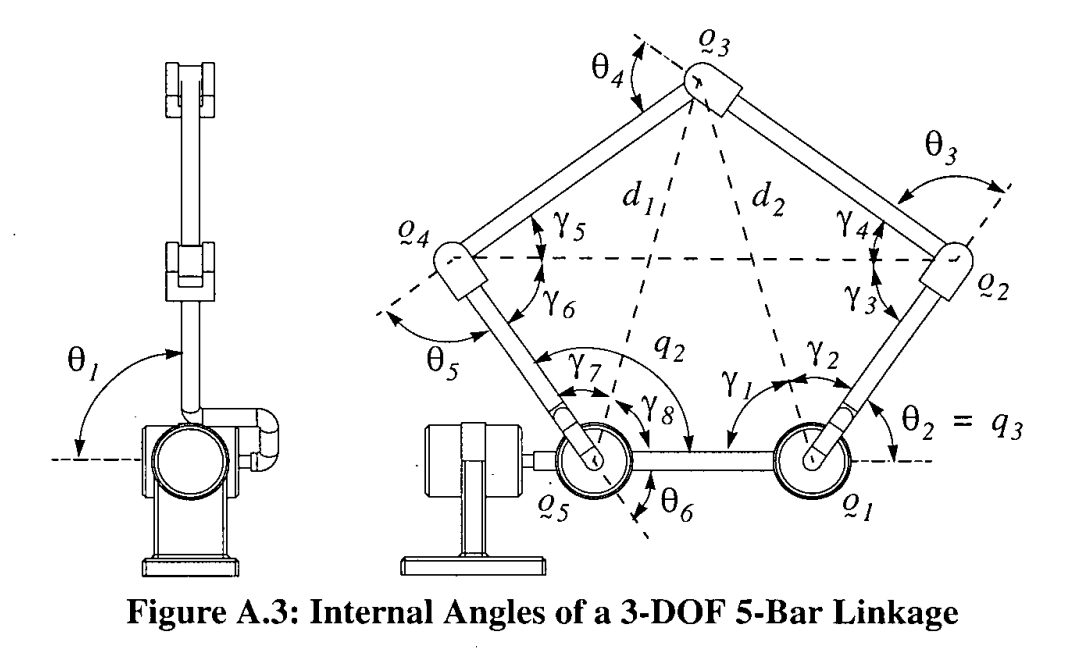

% 2D Inverse Kinematics to solve pseudo joint angle theta3 - [x0, y0 at Q1]
% Again, we do not care about anything past this, our end effector is Q3

q1_2x = l2*cos(theta2);
q1_2y = l2*sin(theta2);
q1_2 = [q1_2x; q1_2y];

% q4_2 is the vector drawn from q2 > q4 drawn above
q4_2x = q1_2x + 2*l1-l5*cos(q2);
q4_2y = q1_2y - l5*sin(q2)

q4_2y = 0

q4_2 = [q4_2x; q4_2y];

gamma3 = 2*atan(norm(q4_2 - q1_2)/norm(q4_2 + q1_2)) * sign(theta2 - atan2(q4_2y,q4_2x))

gamma3 = 1.0550

gamma3 = 2*atan(norm(q4_2 - q1_2)/norm(q4_2 + q1_2)) * sign(theta2 - atan2(q4_2y,q4_2x))

gamma3 = 1.0550


gamma3deg = gamma3 * 360 /6.28

gamma3deg = 60.4793


gamma4 = pi - 2*atan(sqrt(((norm(q4_2) + l3)^2 - l4^2) / (l4^2 - (norm(q4_2) - l3)^2)))

gamma4 = 0.9328

gamma4deg = gamma4 * 360 /6.28

gamma4deg = 53.4701


theta3 = pi - gamma3 - gamma4

theta3 = 1.1538

theta3deg = theta3 * 360 /6.28

theta3deg = 66.1419

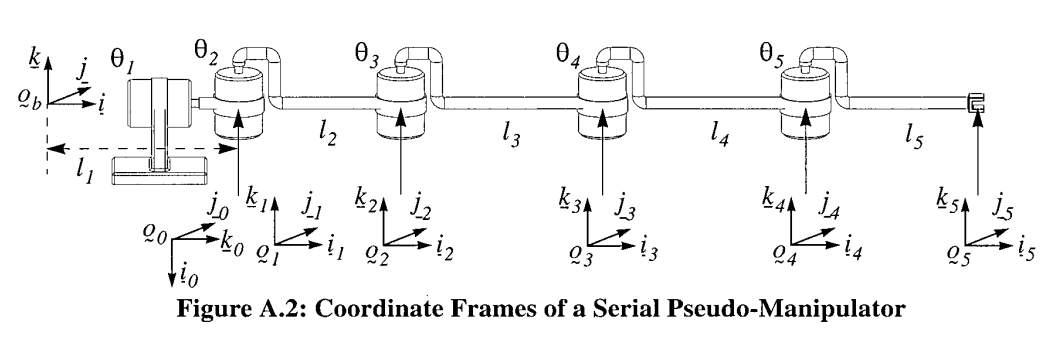

% Matrix Transformations

eul = [0 pi/2 0]; % Z-Y-X, or k-j-i !!!
Cb_0 = eul2rotm(eul);
c = [l1; 0; 0]; 
Tb_0 = zeros(4,4); % initialize empty hom. 4x4 matrix
Tb_0(1:3,1:3) = Cb_0; % insertion of rot 3x3 into hom. 4x4
Tb_0(1:3, 4) = c; % insertion of translation vector into 4x4
Tb_0(4,4) = 1; % insertion of view factor into 4x4
Tb_0 % completed homogeneous 4x4 matrix

Tb_0 =     0.0000         0    1.0000    1.9750
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000



eul = [theta1 -pi/2 0]; 
C0_1 = eul2rotm(eul);
c = [0; 0; 0]; 
T0_1 = zeros(4,4); % initialize empty hom. 4x4 matrix
T0_1(1:3,1:3) = C0_1; % insertion of rot 3x3 into hom. 4x4
T0_1(1:3, 4) = c; % insertion of translation vector into 4x4
T0_1(4,4) = 1; % insertion of view factor into 4x4
T0_1 % completed homogeneous 4x4 matrix

T0_1 =     0.0000   -1.0000   -0.0000         0
    0.0000    0.0000   -1.0000         0
    1.0000         0    0.0000         0
         0         0         0    1.0000



eul = [theta2 0 0]; 
C1_2 = eul2rotm(eul); 
c = C1_2*l2vec; 
T1_2 = zeros(4,4); % initialize empty hom. 4x4 matrix
T1_2(1:3,1:3) = C1_2; % insertion of rot 3x3 into hom. 4x4
T1_2(1:3, 4) = c; % insertion of translation vector into 4x4
T1_2(4,4) = 1; % insertion of view factor into 4x4
T1_2 % completed homogeneous 4x4 matrix

T1_2 =     0.5000   -0.8660         0   10.9500
    0.8660    0.5000         0   18.9660
         0         0    1.0000         0
         0         0         0    1.0000



eul = [theta3 0 0]; 
C2_3 = eul2rotm(eul); 
c = C2_3*l3vec; 
T2_3 = zeros(4,4); % initialize empty hom. 4x4 matrix
T2_3(1:3,1:3) = C2_3; % insertion of rot 3x3 into hom. 4x4
T2_3(1:3, 4) = c; % insertion of translation vector into 4x4
T2_3(4,4) = 1; % insertion of view factor into 4x4
T2_3 % completed homogeneous 4x4 matrix

T2_3 =     0.4050   -0.9143         0    8.7887
    0.9143    0.4050         0   19.8406
         0         0    1.0000         0
         0         0         0    1.0000



% Overall Transformation:
Tb_3 = Tb_0 * T0_1 * T1_2 * T2_3

Tb_3 =    -0.5893   -0.8079    0.0000    0.1369
    0.0000   -0.0000   -1.0000    0.0000
    0.8079   -0.5893    0.0000   36.4975
         0         0         0    1.0000




% Debug parameters:
frame0XYZ = Tb_0(1:3, 4).'

frame0XYZ =     1.9750         0         0



Tb_1 = Tb_0 * T0_1;
frame1XYZ = Tb_1(1:3, 4).'

frame1XYZ =     1.9750         0         0



Tb_2 = Tb_0 * T0_1 * T1_2;
frame2XYZ = Tb_2(1:3, 4).'

frame2XYZ =    12.9250    0.0000   18.9660



%End effector coordinates [x y z]
endEffectorXYZ = Tb_3(1:3, 4).'

endEffectorXYZ =     0.1369    0.0000   36.4975
